%14
aff = 1e14; %a frequency factor
Ea = 77e3;
R = 8.314;
A0 = 0.25;
temp = 293:304

temp =    293   294   295   296   297   298   299   300   301   302   303   304


time = 1:0.2:4

time =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


[t,T] = meshgrid(time, temp);

% k = A*(T/To)^2*exp(-Ea/(R*T))
% A = A0*exp(-k*T)

k = aff*exp(-Ea./(R*T)) %reaction rate

k =     1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720    1.8720
    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845    2.0845
    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194    2.3194
    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790    2.5790
    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655    2.8655
    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816    3.1816
    3.5301    3.5301    3.5301

A = A0*exp(-k.*t) %reactant concentration

A =     0.0385    0.0264    0.0182    0.0125    0.0086    0.0059    0.0041    0.0028    0.0019    0.0013    0.0009    0.0006    0.0004    0.0003    0.0002    0.0001
    0.0311    0.0205    0.0135    0.0089    0.0059    0.0039    0.0025    0.0017    0.0011    0.0007    0.0005    0.0003    0.0002    0.0001    0.0001    0.0001
    0.0246    0.0155    0.0097    0.0061    0.0038    0.0024    0.0015    0.0010    0.0006    0.0004    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000
    0.0190    0.0113    0.0068    0.0040    0.0024    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000
    0.0142    0.0080    0.0045    0.0026    0.0014    0.0008    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0104    0.0055    0.0029    0.0015    0.0008    0.0004    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0073    0.0036    0.0018

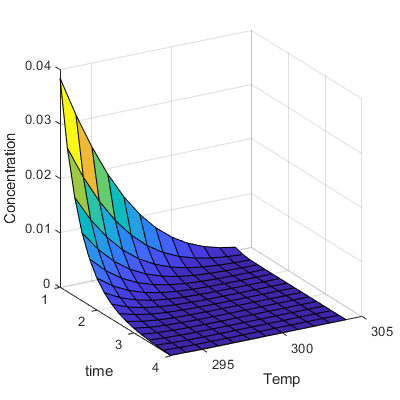

surf(t,T,A)
view(60,20)
xlabel('time'), ylabel('Temp'), zlabel('Concentration')